## Boundary Value Problems

### Start off with a relatively simple example


$$\frac{\partial^2 u}{\partial x^2} = f(x)$$


with $u(1) = a$ and $u(n) = b$ with some function $f(x)$.

### Example 1

Let us assume that $f(x) = x^2 - 3x$. (so the values of $\frac{\partial^2 u}{\partial x^2}}$ should just be 2 so it's easy to check). 


$$\frac{\partial^2 u}{\partial x^2} = x^2 - 3x$$


In order to approximate the second derivative we will use the second derivative midpoint formula:


$$f''(x) \approx \frac{1}{h^2} \cdot [f(x_0 -h) - 2f(x_0) + f(x_0 + h)]$$


which can be found on page 178 of [Richard L. Burden, J. Douglas Faires, Annette M. Burden - Numerical Analysis-Cengage Learning (2015)].

We will coerce this until we can represent it like a system of equations:

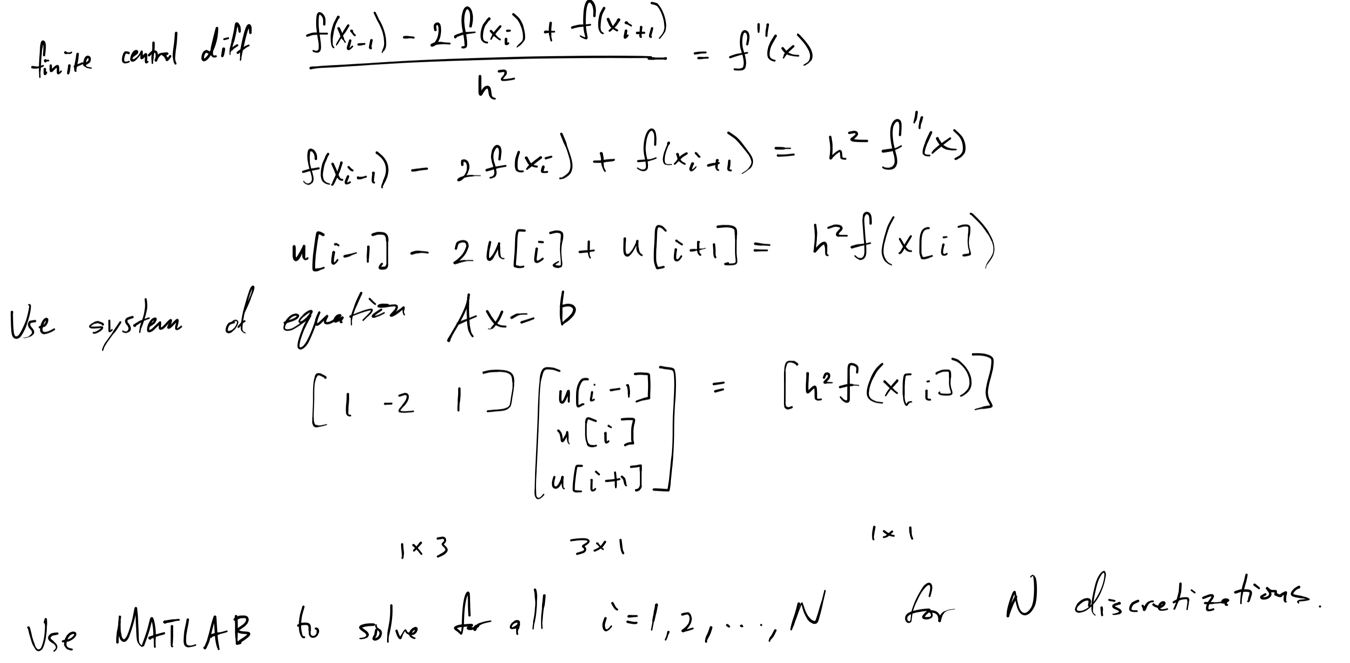

So we will need to construct matrix $A$, a tridiagonal matrix of the coefficients, and the column vector $b$ of $h^2 * f(x_i)$ values and use MATLAB's linear equation solver to get vector the row vector $x$ in the linear equation $Ax=b$ where $x$ actually holds our approximation values for $u(x)$ that satisfies the differential equation $\frac{\partial^2 u}{\partial x^2} = f(x)$. 

We choose an arbitrary function for $f(x)$ for demonstration purposes.

clear;

f = @(x) x^2;
actual_solution = @(x) (x.^4 ./ 12) + 5.*x + 10; % u(x)

N = 100; % num discretizations (including endpoints)
domain_bound_start = 1;
domain_bound_end = 10;
h = (domain_bound_end - domain_bound_start) / N;

% boundary conditions
start_condition = actual_solution(domain_bound_start);
end_condition = actual_solution(domain_bound_end);

A = zeros(N, N);
b = zeros(N,1);
b(1) = start_condition;
b(N) = end_condition;

A(1,1) = 1;
A(N,N) = 1;

x = linspace(domain_bound_start, domain_bound_end, N);

for i = 2:N-1
    A(i,i-1) = 1.0;
    A(i,i) = -2.0;
    A(i,i+1) = 1.0;
    b(i) = h^2 * f(x(i));
end

% Solve
u = A\b;

     1   100



     1   100



     1   100



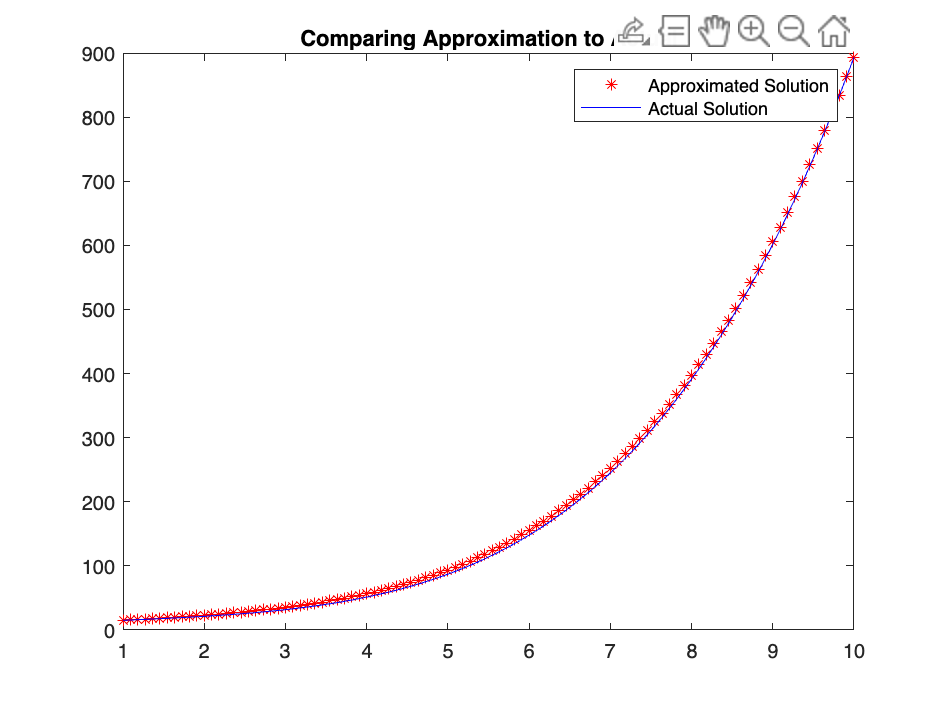


% plot comparing approx against actual to check
fig = figure;
plot(x, u', '*r');
hold on;
plot(x, actual_solution(x), 'b');
legend('Approximated Solution', 'Actual Solution')
title('Comparing Approximation to Actual')
hold off;


% check greatest error
err = zeros(N, 1);
for i = 2:N-1
    err(i) = abs(u(i+1) - 2*u(i) + u(i-1))/h^2 - f(x(i));
end
max_err = max(err)

max_err = 3.0127e-11